 **Exercise 1: Plotting Specific Signals **

Tasks: Plot the continuous-time (CT) signals and discrete-time (DT) signals 

          using subplots. Complete the missing trit_t and sinc_t functions.

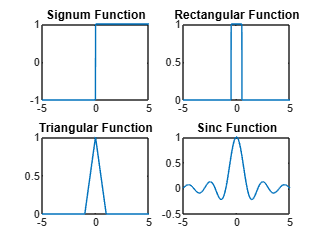


% Continuous-Time (CT) Signals
t = -5:0.01:5;

% Signum function
sgn_t = sign(t);

% Rectangular function (Alternative for rectangularPulse)
rect_t = double(abs(t) <= 0.5);

% Triangular function
tri_t = (1 - abs(t)) .* (abs(t) <= 1);

% Sinc function (Using MATLAB's built-in sinc function)
sinc_t = sinc(t); 

% Plot CT signals
figure;
subplot(2,2,1); plot(t, sgn_t); title('Signum Function');
subplot(2,2,2); plot(t, rect_t); title('Rectangular Function');
subplot(2,2,3); plot(t, tri_t); title('Triangular Function');
subplot(2,2,4); plot(t, sinc_t); title('Sinc Function');

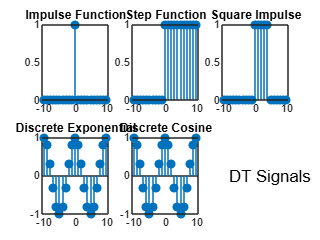


%  Discrete-Time (DT) Signals
n = -10:10;

% Impulse function
delta_n = (n == 0);

% Step function
u_n = (n >= 0);

% Square impulse (nonzero for n = 0,1,2,3,4)
square_n = (n >= 0) & (n < 5);

% Discrete exponential
exp_n = exp(1j * pi * n / 5);

% Discrete cosine (added as a missing subplot)
cos_n = cos(pi * n / 5);

% Plot DT signals in a 2x3 grid so all signals are visible.
figure;
subplot(2,3,1); stem(n, delta_n, 'filled'); title('Impulse Function');
subplot(2,3,2); stem(n, u_n, 'filled'); title('Step Function');
subplot(2,3,3); stem(n, square_n, 'filled'); title('Square Impulse');
subplot(2,3,4); stem(n, real(exp_n), 'filled'); title('Discrete Exponential');
subplot(2,3,5); stem(n, cos_n, 'filled'); title('Discrete Cosine');
% Optionally, leave subplot(2,3,6) empty or use for additional info
subplot(2,3,6); axis off; text(0.1,0.5,'DT Signals','FontSize',12);

 **Exercise 2: Frequency Analysis Using Subplots**

Tasks: Implementing exp_k and exp_l for discrete exponential signals.

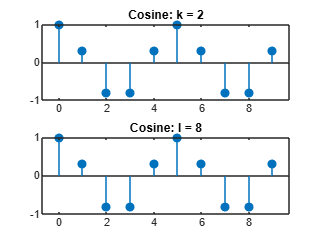


N = 10;
n = 0:N-1;
k = 2;
l = N - k;

% Discrete Cosine signals
cos_k = cos(2*pi*k*n/N);
cos_l = cos(2*pi*l*n/N);

% Discrete Exponential signals
exp_k = exp(1j * 2 * pi * k * n / N);
exp_l = exp(1j * 2 * pi * l * n / N);

% Plot Cosine signals
figure;
subplot(2,1,1); stem(n, cos_k, 'filled'); title(['Cosine: k = ', num2str(k)]);
subplot(2,1,2); stem(n, cos_l, 'filled'); title(['Cosine: l = ', num2str(l)]);

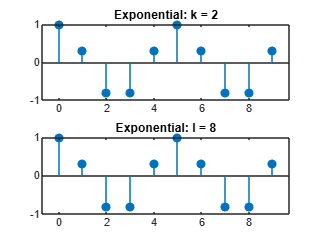


% Plot Exponential signals (real parts)
figure;
subplot(2,1,1); stem(n, real(exp_k), 'filled'); title(['Exponential: k = ', num2str(k)]);
subplot(2,1,2); stem(n, real(exp_l), 'filled'); title(['Exponential: l = ', num2str(l)]);

Exercise 3: Completing Inner Products, Energy, and Power

Tasks: Compute inner products, energy of signals, power of periodic signals,

verify the Cauchy-Schwarz inequality.


% Discrete-Time (DT) Inner Product 
n = 0:9;
x_dt = cos(2*pi*n/10);
y_dt = sin(2*pi*n/10);
inner_dt = sum(x_dt .* conj(y_dt));

% Display DT inner product result
fprintf('DT Inner Product = %.16f\n', inner_dt);

DT Inner Product = -0.0000000000000001



%  Continuous-Time (CT) Inner Product 
t = 0:0.01:1;
x_ct = sin(2*pi*t);
y_ct = cos(2*pi*t);
inner_ct = trapz(t, x_ct .* conj(y_ct));  % Using trapz for numerical integration

% Display CT inner product result
fprintf('CT Inner Product = %.16f\n', inner_ct);

CT Inner Product = 0.0000000000000000



% Energy Calculation
% DT Energy
energy_x_dt = sum(abs(x_dt).^2);
energy_y_dt = sum(abs(y_dt).^2);

% CT Energy
energy_x_ct = trapz(t, abs(x_ct).^2);
energy_y_ct = trapz(t, abs(y_ct).^2);

% Display Energy Results
fprintf('DT Energy of x_dt = %.16f\n', energy_x_dt);

DT Energy of x_dt = 4.9999999999999991


fprintf('DT Energy of y_dt = %.16f\n', energy_y_dt);

DT Energy of y_dt = 5.0000000000000009


fprintf('CT Energy of x_ct = %.16f\n', energy_x_ct);

CT Energy of x_ct = 0.5000000000000000


fprintf('CT Energy of y_ct = %.16f\n', energy_y_ct);

CT Energy of y_ct = 0.5000000000000000



% Power Calculation (Average energy over time) 
power_x_ct = energy_x_ct / (max(t) - min(t));
power_x_dt = energy_x_dt / length(n);

% Display Power Results
fprintf('CT Power of x_ct = %.16f\n', power_x_ct);

CT Power of x_ct = 0.5000000000000000


fprintf('DT Power of x_dt = %.16f\n', power_x_dt);

DT Power of x_dt = 0.4999999999999999



%  Verify Cauchy-Schwarz Inequality 
cauchy_schwarz_dt = abs(inner_dt) <= sqrt(energy_x_dt * energy_y_dt);
cauchy_schwarz_ct = abs(inner_ct) <= sqrt(energy_x_ct * energy_y_ct);

% Display Cauchy-Schwarz Results
disp(['Cauchy-Schwarz DT holds: ', num2str(cauchy_schwarz_dt)]);

Cauchy-Schwarz DT holds: 1


disp(['Cauchy-Schwarz CT holds: ', num2str(cauchy_schwarz_ct)]);

Cauchy-Schwarz CT holds: 1


**Exercise 4: System Classifications**

Tasks: Check Linearity and Time-Invariance for CT and DT systems.

            Check Causality and Stability of given systems.


%  Linearity and Time-Invariance (CT)
t = 0:0.01:5;
x1 = sin(2*pi*t);
x2 = cos(2*pi*t);
y1 = x1 + circshift(x1, 100);
y2 = x2 + circshift(x2, 100);
y3 = x1 + x2 + circshift(x1 + x2, 100);
is_linear_ct = isequal(y1 + y2, y3);

% Linearity and Time-Invariance (DT) 
n = 0:50;
x1_dt = sin(2*pi*n/10);
x2_dt = cos(2*pi*n/10);
y1_dt = x1_dt + circshift(x1_dt, 10);
y2_dt = x2_dt + circshift(x2_dt, 10);
y3_dt = x1_dt + x2_dt + circshift(x1_dt + x2_dt, 10);
is_linear_dt = isequal(y1_dt + y2_dt, y3_dt);

% Causality and Stability
% For CT System: Integral from -∞ to t (example representation)
syms tau t_sym;
x_tau = exp(-tau);
y_t = int(x_tau, tau, -inf, t_sym); % This is an example; in practice, a CT system's causality is determined by its impulse response.

% For DT System: Summation from -∞ to n (example representation)
syms k n_sym;
x_k = k^2;
y_n = symsum(x_k, k, -inf, n_sym); % Example sum (diverges, but used here illustratively)

% Checking causality (using the signal domains)
is_causal_ct = all(t >= 0); % System is causal if t >= 0 (for t vector defined earlier)
is_stable_ct = energy_x_ct < inf; % System is stable if it has finite energy

is_causal_dt = all(n >= 0); % System is causal if n >= 0
is_stable_dt = energy_x_dt < inf; % System is stable if it has finite energy

% Display system classification results
disp(['System is Linear (CT): ', num2str(is_linear_ct)]);

System is Linear (CT): 0


disp(['System is Linear (DT): ', num2str(is_linear_dt)]);

System is Linear (DT): 0


disp(['System is Causal (CT): ', num2str(is_causal_ct)]);

System is Causal (CT): 1


disp(['System is Causal (DT): ', num2str(is_causal_dt)]);

System is Causal (DT): 1


disp(['System is Stable (CT): ', num2str(is_stable_ct)]);

System is Stable (CT): 1


disp(['System is Stable (DT): ', num2str(is_stable_dt)]);

System is Stable (DT): 1
